clear; close all;


[ProgressClassFile, ProgressClassFolder, tf] = uigetfile("F:\YuLab\Work\GPS\Data\*.mat");
if ~tf
    return;
end
ProgressClassPath = fullfile(ProgressClassFolder, ProgressClassFile);

load(ProgressClassPath);

FigFolder = fullfile(ProgressClassFolder, "TestFigs");
if ~isfolder(FigFolder)
    mkdir(FigFolder);
end


FPs = obj.MixedFP;

session_control = find(obj.Label=="Control");
session_chemo = find(obj.Label=="Chemo");

beh = obj.BehavTable;


session_sep = find(diff(double(beh.SessionDate))~=0);
time_sep = zeros(1, length(session_sep));
for i = 1:length(session_sep)
    time_sep(i) = mean(beh.TrialStartTimeProgress([session_sep(i) session_sep(i)+1]));
end

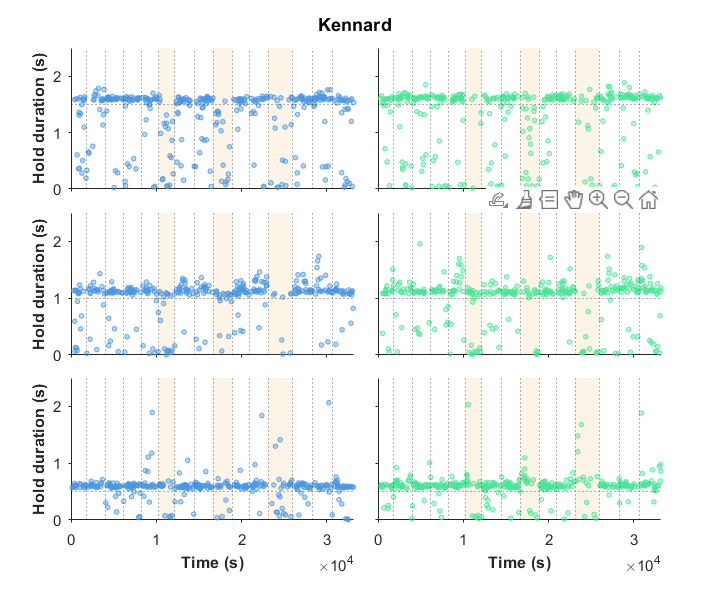

f = figure(31); clf(f);
set(f, "Units", "centimeters", "Position", [5 5 15 12.5], 'Visible', 'on', 'Color', 'w');
set_fig_title(f, obj.Subject);

ax_sz = [6 3];
pos = {
    [1.5 1.5], [8 1.5];
    [1.5 5]  , [8 5];
    [1.5 8.5], [8 8.5]
    };
for fp=1:3
    for p=1:2
        ax = axes(f, 'NextPlot', 'add', 'Units','centimeters', 'Position', [pos{fp, p}, ax_sz], 'FontSize', 9, 'TickDir', 'out');

        id = beh.PortCorrect==p & beh.FP==FPs(fp);
        if ~isempty(session_chemo)
            for i=1:length(session_chemo)
                s = session_chemo(i);
                if s==obj.NumSessions
                    fill(ax, [beh.TrialStartTimeProgress([end end])' time_sep([s s])], [0 2.5 2.5 0], 'r', ...
                        'FaceColor', GPSColor.Treat, 'FaceAlpha', .1, 'EdgeColor', 'none');
                elseif s==1
                    fill(ax, [0 0 time_sep([s s])], [0 2.5 2.5 0], 'r', ...
                        'FaceColor', GPSColor.Treat, 'FaceAlpha', .1, 'EdgeColor', 'none');
                else
                    fill(ax, time_sep([s-1 s-1 s s]), [0 2.5 2.5 0], 'r', ...
                        'FaceColor', GPSColor.Treat, 'FaceAlpha', .1, 'EdgeColor', 'none');
                end

            end
        end
        scatter(ax, beh.TrialStartTimeProgress(id), beh.HoldDuration(id), 8, GPSColor.("Port"+obj.Ports(p)), "filled", ...
            "MarkerEdgeColor", "flat", 'MarkerEdgeAlpha', .8, ...
            'MarkerFaceColor', 'flat', 'MarkerFaceAlpha', .4);
        yline(ax, FPs(fp), 'LineWidth', .5, 'LineStyle', ':');
        xline(ax, time_sep, 'LineWidth', .5, 'LineStyle', ':');

        xlim([0 beh.TrialStartTimeProgress(end)]); ylim(ax, [0 2.5]);

        if fp==1
            xlabel(ax, "Time (s)", "FontWeight", "bold");
        else
            set(ax, 'XTickLabel', []);
        end
        if p==1
            ylabel(ax, "Hold duration (s)", 'FontWeight', 'bold');
        else
            set(ax, 'YTickLabel', []);
        end

    end
end


fig_name = sprintf("Test_%s_HD_progress_%s.jpg", obj.Task, obj.Subject);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(f, fig_path, 'Resolution', 600);


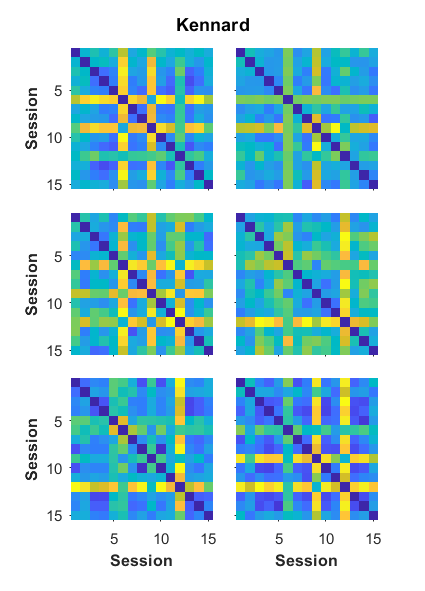

f = figure(32); clf(f);
set(f, "Units", "centimeters", "Position", [5 5 9 12.5], 'Visible', 'on', 'Color', 'w');
set_fig_title(f, obj.Subject);

ax_sz = [3 3];
pos = {
    [1.5 1.5], [5 1.5];
    [1.5 5]  , [5 5];
    [1.5 8.5], [5 8.5]
    };
for fp=1:3
    for p=1:2
        ax = axes(f, 'NextPlot', 'add', 'Units','centimeters', 'Position', [pos{fp, p}, ax_sz], 'FontSize', 9, 'TickDir', 'out', 'YDir', 'reverse');

        KS_mat = zeros(obj.NumSessions);
        TV_mat = zeros(obj.NumSessions);
        for m=1:obj.NumSessions
            for n=m:obj.NumSessions
                id_m = beh.PortCorrect==p & beh.FP==FPs(fp) & beh.SessionDate==obj.Sessions(m);
                id_n = beh.PortCorrect==p & beh.FP==FPs(fp) & beh.SessionDate==obj.Sessions(n);
                [~, KS_mat(m,n)] = kstest2(beh.HoldDuration(id_m), beh.HoldDuration(id_n));
                TV_mat(m,n) = .5*sum(abs(obj.HDPDF{m}{fp,p} - obj.HDPDF{n}{fp,p}));
            end
        end

        TV_mat = TV_mat + TV_mat';
        imagesc(ax, TV_mat);

        xlim(ax, [.5 obj.NumSessions+.5]); ylim(ax, [.5 obj.NumSessions+.5]);

        if fp==1
            xlabel(ax, "Session", "FontWeight", "bold");
        else
            set(ax, 'XTickLabel', []);
        end
        if p==1
            ylabel(ax, "Session", 'FontWeight', 'bold');
        else
            set(ax, 'YTickLabel', []);
        end
    end
end

fig_name = sprintf("Test_%s_HD_total_var_%s.jpg", obj.Task, obj.Subject);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(f, fig_path, 'Resolution', 600);